几何网格参数

L=1.5*10^(-2);
W=1*10^(-3);
h=1;
b = W/2;
dL=L/300;
dW=W/20;

L_crack = 0;
A = dL*dW;
Nelement=round(L/dL*W/dW);
Nelement_crack = round(L_crack/dL);
% Nnode_crack = 2*Nelement_crack-1;
Nnode_crack = 0;
Nnode=round((2*L/dL+1)*(2*W/dW+1)+Nnode_crack-fix((2*W/dW+1)/2)*L/dL); % crack area added nodes
%% 节点信息
[ Coordinate ] = Node_setting( Nnode,Nnode_crack,L_crack,L,dL,dW  );
Coordinate = Coordinate/b; % 坐标归一化

x = Coordinate(:,1);
y = Coordinate(:,2);
L_crack = b;
W_crack = 0.05*b;
%% 边界节点
L_crack = L_crack/b;
W_crack = W_crack/b;

crack =  find((y >= W-W_crack) .* (x <= L_crack/2+b/10 ) .* (x >= -L_crack/2-b/10)); % 矩形缺陷
crack = find((x>=-L_crack/2) .*(x<=L_crack/2) ...
	.*(y>=(2*W_crack/L_crack)*x + 1-W_crack) .*(y>=(-2*W_crack/L_crack)*x+ 1-W_crack)); % 三角形缺陷
crack = crack';
length(crack)

ans =     21


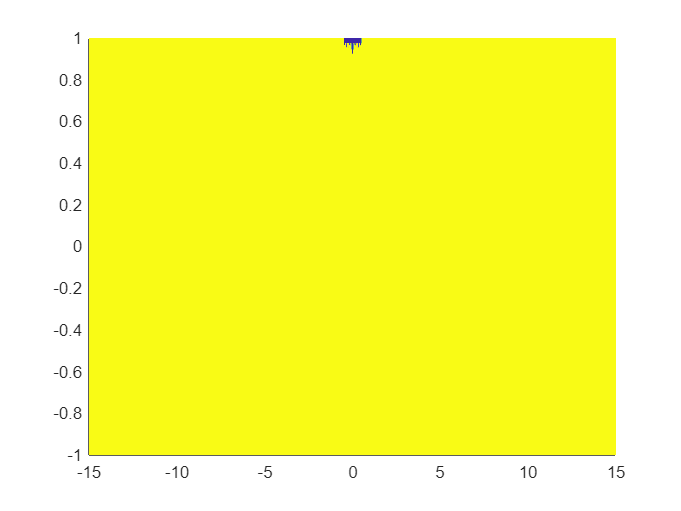

U = ones(size(Coordinate,1),1);
U(crack) = 0;
plot_pcolor(Coordinate,U);

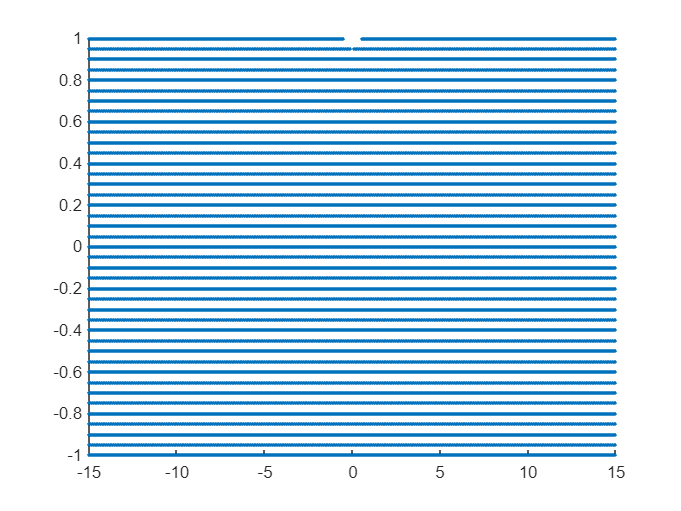


U3 = U; U3(crack) = nan;
plot_plot3(Coordinate,U3);
view(2)